clc;clear;close all;
load Traininginfo.mat %load properties into the model
load Testinginfo.mat
tree=fitctree(Traininginfo, 'state') %creates a decision tree classification model

tree =   ClassificationTree
           PredictorNames: {'h vs. uh'  'TBint'}
             ResponseName: 'state'
    CategoricalPredictors: []
               ClassNames: {'N'  'T'}
           ScoreTransform: 'none'
          NumObservations: 50


  Properties, Methods


prediction=predict(tree, Testinginfo);
right=prediction==Testinginfo.state;
accuracy=sum(right)/numel(right); %determines the accuracy of the model
percentacc=accuracy*100

percentacc = 40

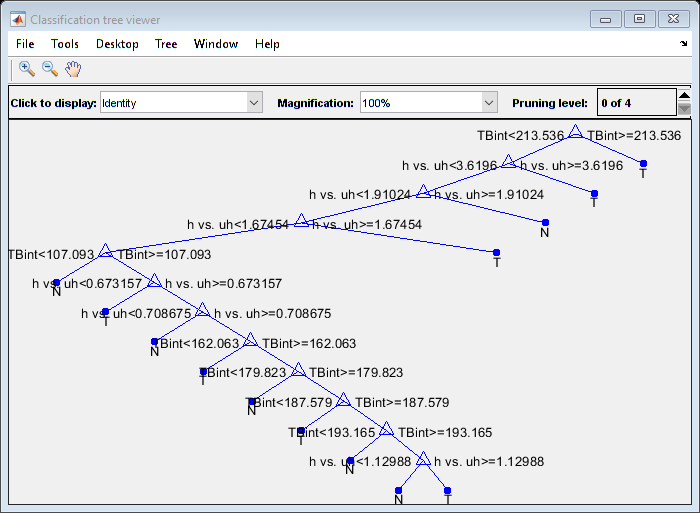


view(tree,"Mode","graph") %displays the decision tree

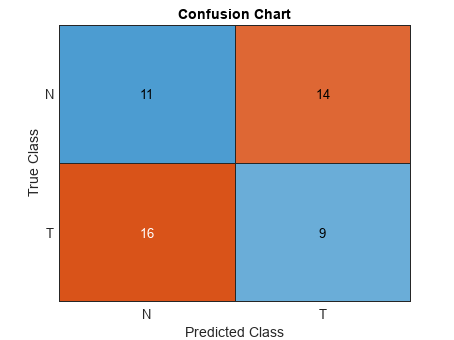


sinfo=Testinginfo.state; %displays the confusion chart
sinfo=cellstr(sinfo);
confusionchart(sinfo,prediction)
title("Confusion Matrix")